# Brusshless Motod Complete model with ESC

The hole diagram is depiccted in the following figure.

# 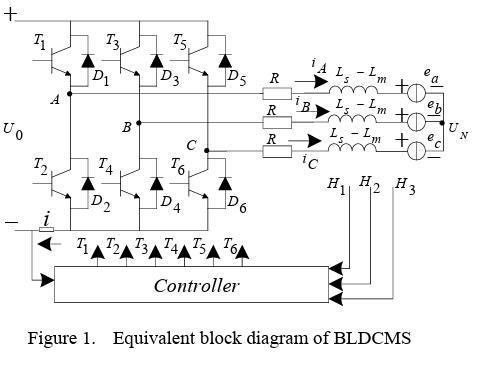

The imput of the controller is a inpulse function

Where T is switch cycle; D is duty cycle and 0 $\leq$D $\leq$ 1, k = 0,1,2...

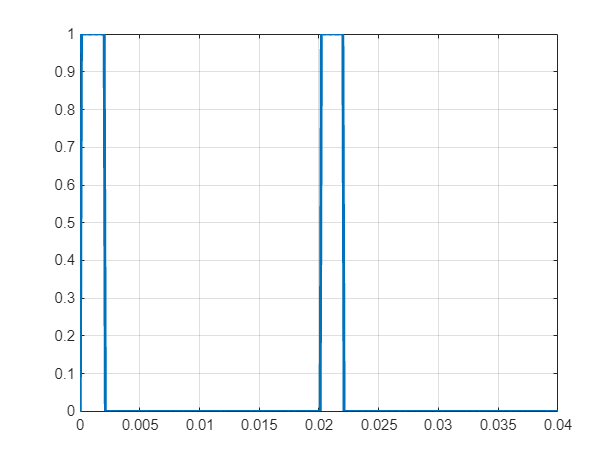

rw.T = 1/50; %%Segun la funcion servo.h de arduino
%rw.D  = 1500*1e-3; %%Dutty Cycle
rw.D  = 2000*1E-6/rw.T; %%Dutty Cycle (1000us -- 0%rpm, 2000us--100%rpm)

time = 0:1E-4:2*rw.T;

pwm = myPW(rw.T,rw.D,time);

figure()    
plot(time,pwm,'LineWidth',2); grid on;

function u = myPW(T,D,t)
u = zeros(1,length(t));
K = 0;
 for i=1:length(t)
    if (t(i) > K*T && t(i) <= (K+D)*T)
        u(i) = 1;
    elseif (t(i) > (K+D)*T && t(i) <= (K+1)*T)
        u(i) = 0;
    end
    if(t(i)>(K+1)*T)
        K = K+1;
    end
 end
end

The hole diagram system for the RW is 

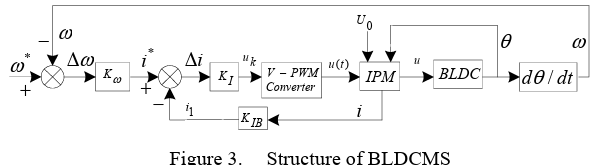

Suppose EMF is 120 flattened trapezoidal waveform  and phase current is 120 rectangular waveform, in a, b, c  coordinate system, a BLDC motor can be represented as 

Where u_a, u_b, u_c are terminal voltages with reference to ground e_a, e_b, e_c are back EMF, i_a, i_b, and i_c are phase current, R is phase resistance,L_s, L_m are self and mutual phase inductance respectively.

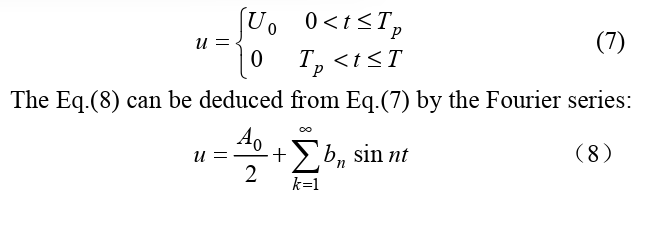

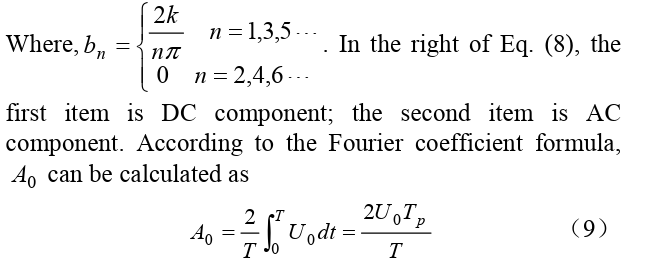

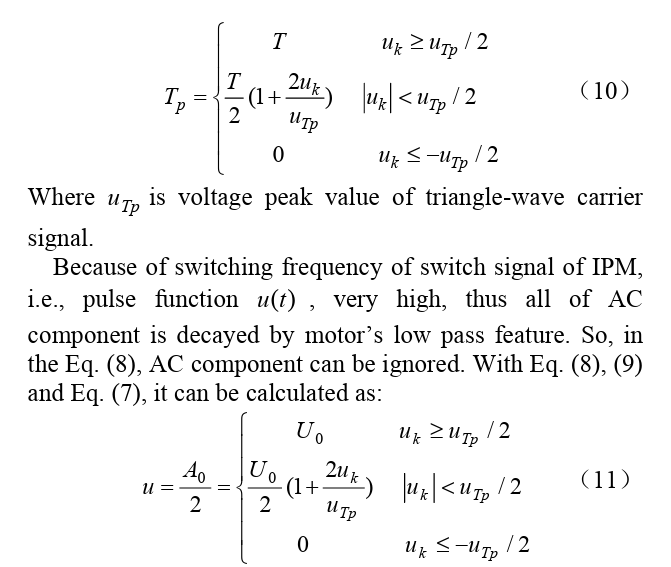

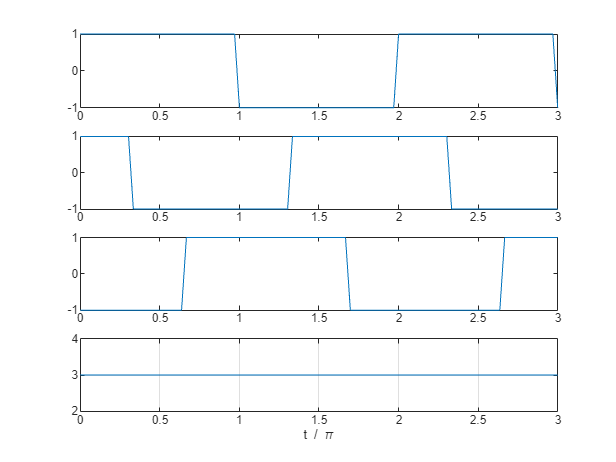

t = linspace(0,3*pi)';
x  = square(t);
x1 = square(t+2*pi/3);
x2 = square(t-2*pi/3);

figure
subplot(4,1,1)
plot(t/pi,x); hold on;
subplot(4,1,2)
plot(t/pi,x1);
subplot(4,1,3)
plot(t/pi,x2);
subplot(4,1,4)
plot(t/pi,(abs(x)+abs(x1)+abs(x2)),'')
xlabel('t / \pi')
grid on

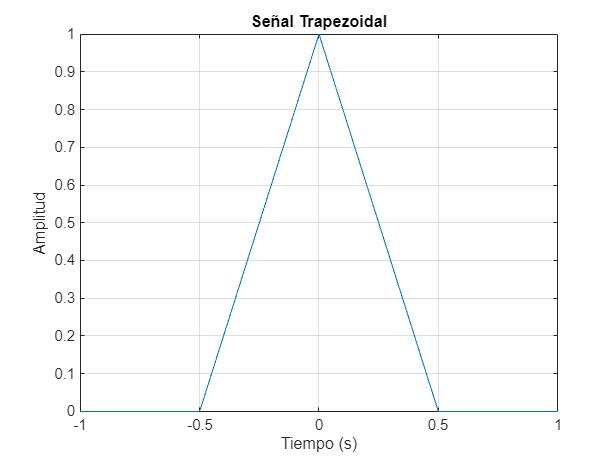

% Parámetros de la señal
T = 1; % Duración de la señal
Ts = 0.01; % Tiempo de muestreo
t = -T:Ts:T; % Vector de tiempo

% Generar la señal trapezoidal
y = tripuls(t, T);

% Graficar la señal
figure;
plot(t, y);
title('Señal Trapezoidal');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

% % %%%Nominal motor values
% % motor.kt=25.5E-3;
% % 
% % motor.J=92.5E-9;
% % motor.B=1E-5;
% % %motor.Kc=1E-5;
% % 
% % motor.L=0.56E-3;
% % motor.R=1.2;
% % motor.Ke=374*pi/30;
% % %motor.d =0;
% % %motor.ws = 1;

%  %%%Nominal motor values
% motor.kt = 54.8817;
% % % 
% motor.J  = 0.0541874;
% motor.B  = 0.00029245;
% motor.Kc = 33.2032;
% % % 
% %motor.L  = 4.08428;
% motor.L  = 0.999;
% motor.R  = 0.963385;
% motor.Ke = 0.023863;
% %% %motor.d =0;
% %% %motor.ws = 1;

 %%%Nominal motor values
motor.kt = 0.000459463;
% % 
%motor.J  = 0.0901343;
motor.J  = 2.55E-5;
motor.B  = 4.88827e-07;
motor.Kc = 0.000461168;
% % 
%motor.L  = 4.08428;
%motor.L  = 0.999800E-3;
motor.L  = 0.56E-3;
%motor.R  = 0.579878;
motor.R  = 1.2;
motor.Ke = 1.19852e-05;
%% %motor.d =0;
%% %motor.ws = 1;



initial = cell2mat(struct2cell(motor));
%%%1. Read data measured from the experiment
nombre_archivo = 'RPMdata1.xlsx';
%dt = 1E-3;      %%Set sample time
dt = 1;      %%Set sample time

%%%Read Excel file
datos = readtable(nombre_archivo);
%%%Add voltage equivales
datos.voltage = ((datos.Input_PWM-1100)*(24/800))-12; %% asuming from -12 to 12 v
%%%Interpolate data to set the desired sampple time
[newDatos.time,newDatos.RPM] = setSampleTime(datos.time_s,datos.Velocidad_rpm,dt);
[~,newDatos.current] = setSampleTime(datos.time_s,datos.Current_A,dt);
[~,newDatos.voltage] = setSampleTime(datos.time_s,datos.voltage,dt);
%%%Update Signs
newDatos.RPM = sign(newDatos.voltage).*newDatos.RPM;
newDatos.current = sign(newDatos.voltage).*(newDatos.current-0.025);


% 2. Represent the estimation data as an |iddata| object. 
y = [newDatos.RPM*pi/30;newDatos.current]';
u = newDatos.voltage';

z = iddata(y, u, dt, 'Name', 'DC-motor');
%%
% 3. Specify input and output signal names, start time and time units. 
z.InputName = 'Voltage';
z.InputUnit =  'V';
z.OutputName = {'Angular rate', 'Motor current'};
z.OutputUnit = {'rad/s', 'A'};
z.Tstart = 0;
z.TimeUnit = 's';

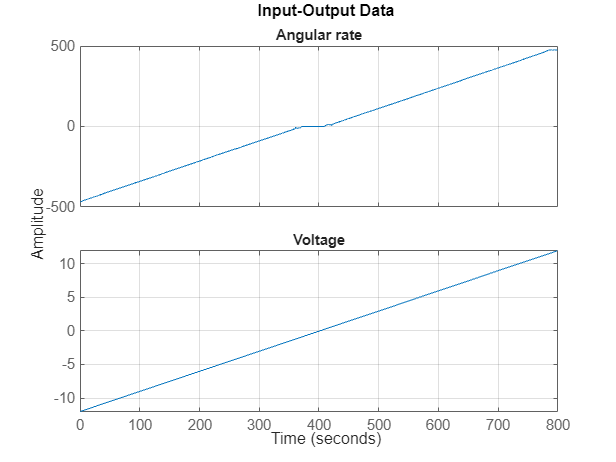

% 4. Plot the data.
%
% The data is shown in two plot windows.
figure('Name', [z.Name ': Current input -> Angular rate output']);
plot(z(:, 1, 1)); grid on;  % Plot first input-output pair (Voltage -> Angular position).

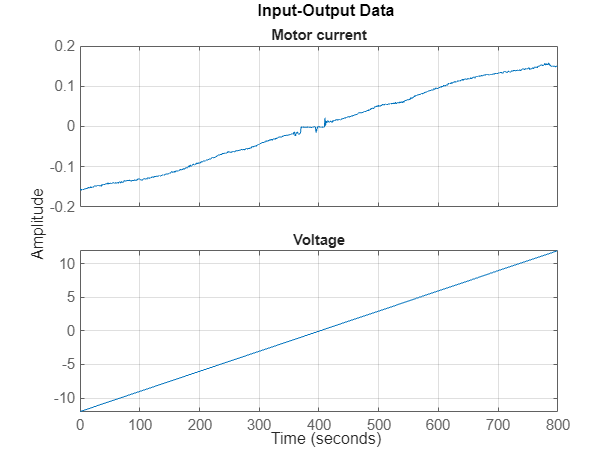

figure('Name', [z.Name ': Voltage input -> Motor current output']);
plot(z(:, 2, 1));  grid on; % Plot second input-output pair (Voltage -> Angular velocity).

%% Linear Modeling of the DC-Motor
% 1. Represent the DC motor structure in a function.  
%%%Check BrushelessModel.m file
%%


% 2. Represent the DC motor dynamics using an |idnlgrey| object.
%
% The model describes how the inputs generate the outputs using the state
% equation(s).
FileName      = 'BrushelessModel';       % File describing the model structure.
Order         = [2 1 2];           % Model orders [ny nu nx].
%Parameters    = [1; 0.28];        % Initial parameters. Np = 2.
Parameters    = initial';          % Initial parameters. Np = 3.
InitialStates = [-500; 0.15-0.025];            % Initial initial states.
%InitialStates = [0; 0];            % Initial initial states.
Ts            = 0;                 % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts, ...
                'Name', 'DC-motor');

%%
%
% 3. Specify input and output names, and units.
set(nlgr, 'InputName', 'Voltage', 'InputUnit', 'V',               ...
          'OutputName', {'Angular rate', 'Motor current'}, ...
          'OutputUnit', {'rad/s', 'A'},                         ...
          'TimeUnit', 's');

%%
% 
% 4. Specify names and units of the initial states and parameters.
nlgr = setinit(nlgr, 'Name',  {'Angular rate', 'Motor current'});
nlgr = setinit(nlgr, 'Unit', {'rad/s', 'A'});
%nlgr = setpar(nlgr, 'Name', {'Torque constant' 'Rotor inertia' 'Constante de friccion viscosa' 'Inductancia' 'Resistencia' 'Constante contraelectromotriz' });
%nlgr = setpar(nlgr, 'Unit', {'N*m/A' 'kg*m^2' 'N*m*s' 'H' 'R' 'V/(Rad/s)' });

nlgr = setpar(nlgr, 'Name', {'Torque constant' 'Rotor inertia' 'Constante de friccion viscosa' 'Constante de friccion de Coulomb' 'Inductancia' 'Resistencia' 'Constante contraelectromotriz' });
nlgr = setpar(nlgr, 'Unit', {'N*m/A' 'kg*m^2' 'N*m*s' 'N*m*s' 'H' 'R' 'V/(Rad/s)' });

%nlgr = setpar(nlgr, 'Name', {'Torque constant' 'Rotor inertia' 'Constante de friccion viscosa' ...
%    'Constante de friccion de Coulomb' 'Inductancia' 'Resistencia' 'Constante contraelectromotriz' 'Starting Torque' ...
%    'Stribeck angular rate'});
%nlgr = setpar(nlgr, 'Unit', {'N*m/A' 'kg*m^2' 'N*m*s' 'N*m*s' 'H' 'R' 'V/(Rad/s)' 'N*m' 'rad/s'});

%% 
%
% You can also use |setinit| and |setpar| to assign values, minima, maxima,
% and estimation status for all initial states or parameters
% simultaneously.
%
% 5. View the initial model.
%
% a. Get basic information about the model.
%
% The DC-motor has 2 (initial) states and 2 model parameters.
size(nlgr)

Nonlinear grey-box model with 2 outputs, 1 inputs, 2 states and 7 parameters (7 free).


%%
%
% b. View the initial states and parameters.
%
% Both the initial states and parameters are structure arrays. The fields
% specify the properties of an individual initial state or parameter. Type
% |help idnlgrey.InitialStates| and |help idnlgrey.Parameters| for
% more information.
nlgr.Parameters(1).Minimum = 0;
nlgr.Parameters(1)

ans = struct with fields:
       Name: 'Torque constant'
       Unit: 'N*m/A'
      Value: 4.5946e-04
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(2).Minimum = eps(0);
nlgr.Parameters(2).Fixed = 1;
nlgr.Parameters(2)

ans = struct with fields:
       Name: 'Rotor inertia'
       Unit: 'kg*m^2'
      Value: 2.5500e-05
    Minimum: 4.9407e-324
    Maximum: Inf
      Fixed: 1


nlgr.Parameters(3).Minimum = 0 ;
nlgr.Parameters(3)

ans = struct with fields:
       Name: 'Constante de friccion viscosa'
       Unit: 'N*m*s'
      Value: 4.8883e-07
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(4).Minimum = 0;
nlgr.Parameters(4)

ans = struct with fields:
       Name: 'Constante de friccion de Coulomb'
       Unit: 'N*m*s'
      Value: 4.6117e-04
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(5).Minimum = eps(0);
nlgr.Parameters(5).Maximum = 1.5E-3;
nlgr.Parameters(5).Fixed = 0;
nlgr.Parameters(5)

ans = struct with fields:
       Name: 'Inductancia'
       Unit: 'H'
      Value: 5.6000e-04
    Minimum: 4.9407e-324
    Maximum: 0.0015
      Fixed: 0


nlgr.Parameters(6).Minimum = 0;
nlgr.Parameters(6).Maximum = 5;
nlgr.Parameters(6).Fixed = 0;
nlgr.Parameters(6)

ans = struct with fields:
       Name: 'Resistencia'
       Unit: 'R'
      Value: 1.2000
    Minimum: 0
    Maximum: 5
      Fixed: 0


nlgr.Parameters(7).Minimum = eps;
nlgr.Parameters(7)

ans = struct with fields:
       Name: 'Constante contraelectromotriz'
       Unit: 'V/(Rad/s)'
      Value: 1.1985e-05
    Minimum: 2.2204e-16
    Maximum: Inf
      Fixed: 0



% nlgr.Parameters(8).Minimum = 0;
% nlgr.Parameters(8)
% nlgr.Parameters(9).Minimum = 1E-6;
% nlgr.Parameters(9).Fixed = 1;
% nlgr.Parameters(9)

%%
%
% c. Retrieve information for all initial states or model parameters in one
% call.
% 
% For example, obtain information on initial states that are fixed (not
% estimated) and the minima of all model parameters.
getinit(nlgr, 'Fixed')

ans = 2×1 cell array
    {[1]}
    {[1]}


getpar(nlgr, 'Min')

ans = 7×1 cell array
    {[          0]}
    {[4.9407e-324]}
    {[          0]}
    {[          0]}
    {[4.9407e-324]}
    {[          0]}
    {[ 2.2204e-16]}


%%
%
% d. Obtain basic information about the object:
nlgr

nlgr =

Continuous-time nonlinear grey-box model defined by 'BrushelessModel' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p7)
    y(t) = H(t, u(t), x(t), p1, ..., p7) + e(t)

 with 1 input(s), 2 state(s), 2 output(s), and 6 free parameter(s) (out of 7).

Name: DC-motor

Status:                                                         
Created by direct construction or transformation. Not estimated.

Model Properties


%%
% Use |get| to obtain more information about the model properties. The
% |idnlgrey| object shares many properties of parametric linear model
% objects.
get(nlgr)

             FileName: 'BrushelessModel'
                Order: [1×1 struct]
           Parameters: [7×1 struct]
        InitialStates: [2×1 struct]
         FileArgument: {}
    SimulationOptions: [1×1 struct]
         TimeVariable: 't'
        NoiseVariance: [2×2 double]
            InputName: {'Voltage'}
            InputUnit: {'V'}
           InputGroup: [1×1 struct]
           OutputName: {2×1 cell}
           OutputUnit: {2×1 cell}
          OutputGroup: [1×1 struct]
                Notes: [0×1 string]
             UserData: []
                 Name: 'DC-motor'
                   Ts: 0
             TimeUnit: 'seconds'
               Report: [1×1 idresults.nlgreyest]



%% Performance Evaluation of the Initial DC-Motor Model
%
% Before estimating the parameters |tau| and |k|, simulate the output of
% the system with the parameter guesses using the default differential
% equation solver (a Runge-Kutta 45 solver with adaptive step length
% adjustment). The simulation options are specified using the
% "SimulationOptions" model property.
%
% 1. Set the absolute and relative error tolerances to
% small values (|1e-6| and |1e-5|, respectively).
nlgr.SimulationOptions.AbsTol = 1e-6;
nlgr.SimulationOptions.RelTol = 1e-5;

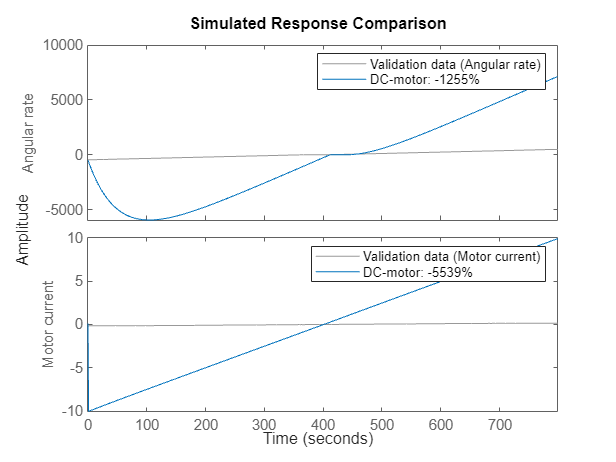

%%
%
% 2. Compare the simulated output with the measured data.
%
% |compare| displays both measured and simulated outputs of one or more
% models, whereas |predict|, called with the same input arguments, displays
% the simulated outputs.
%
% The simulated and measured outputs are shown in a plot window.
compare(z, nlgr);

%% Parameter Estimation
% Estimate the parameters and initial states using |nlgreyest|, which is a
% prediction error minimization method for nonlinear grey box models. The
% estimation options, such as the choice of estimation progress display,
% are specified using the "nlgreyestOptions" option set.
nlgr = setinit(nlgr, 'Fixed', {false false}); % Estimate the initial states.
opt = nlgreyestOptions('Display', 'on');
nlgr = nlgreyest(z, nlgr, opt);

%% Performance Evaluation of the Estimated DC-Motor Model
% 1. Review the information about the estimation process.
%
% This information is stored in the |Report| property of the
% |idnlgrey| object. The property also contains information about how the
% model was estimated, such as solver and search method, data set, and why
% the estimation was terminated.
nlgr.Report

ans =          Status: 'Estimated using NLGREYEST'
         Method: 'Solver: ode45; Search: lsqnonlin'
            Fit: [1×1 struct]
     Parameters: [1×1 struct]
    OptionsUsed: [1×1 idoptions.nlgreyest]
      RandState: []
       DataUsed: [1×1 struct]
    Termination: [1×1 struct]


fprintf('\n\nThe search termination condition:\n')



The search termination condition:


nlgr.Report.Termination

ans = struct with fields:
                 WhyStop: 'Change in parameters was less than the specified tolerance.'
              Iterations: 2
    FirstOrderOptimality: 1.9269e+16
                FcnCount: 3
               Algorithm: 'trust-region-reflective'


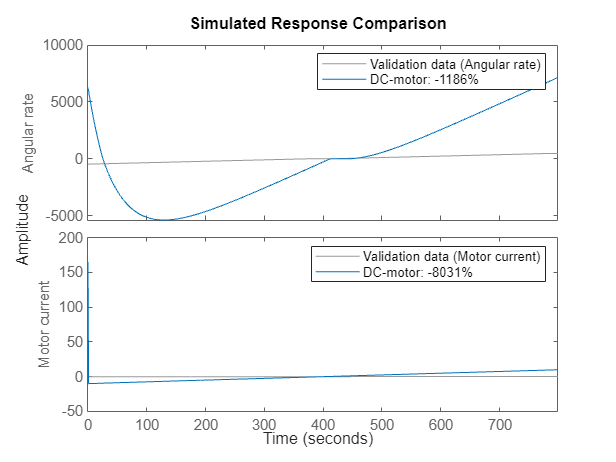

%%
% 2. Evaluate the model quality by comparing simulated and measured
% outputs.
% 
% The fits are 98% and 84%, which indicate that the estimated model
% captures the dynamics of the DC motor well.
compare(z, nlgr);

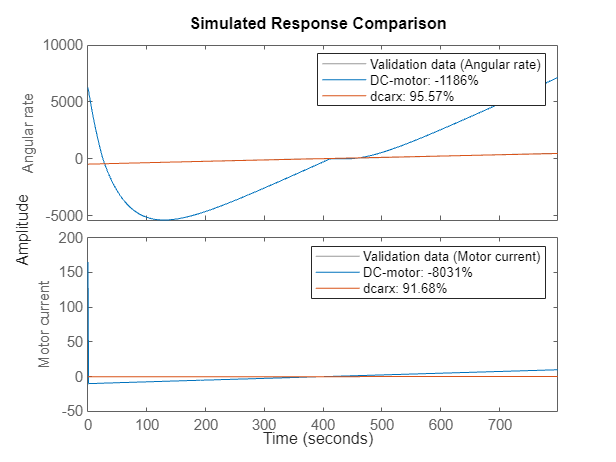

%%
% *Figure 4:* Comparison between measured outputs and the simulated outputs
% of the estimated IDNLGREY DC-motor model.

%%
%
% 3. Compare the performance of the |idnlgrey| model with a second-order
% ARX model.
na = [2 2; 2 2];
nb = [2; 2];
nk = [1; 1];
dcarx = arx(z, [na nb nk]);
compare(z, nlgr, dcarx);

%%
% 4. Check the prediction errors.
%
% The prediction errors obtained are small and are centered around zero
% (non-biased).
pe(z, nlgr);

%%Simulation
%**************************************************************************
% AUTHOR: Brayan Espinoza 22/10/2020
% DESCRIPTION: 
% This program perform the simulation for reaction wheels that will be used
% in the Cubesat reaction wheels.
% IMPORTANT: This a simplification that not takes into account the fase
% change dynamics.
% 
% *************************************************************************

% Clear old variables and close all windows and graphs 
%clc
%clear
%close all;

% Simulation control parameters
%n=100000;            %Number of iterations
Tf=400;              %Simulation time
%t=linspace(0,Tf,n);  %Vector time
dt = 0.1;
t = 0:dt:Tf;
n = length(t);

%%%Nominal motor values
motor.kt = 10;
motor.J  = 92.5E-9;
motor.B  = 0.2;
%motor.Kc=1E-5;

motor.L  = 0.56E-3;
motor.R  = 1.2;
motor.Ke = 0.85;
%motor.d =0;
%motor.ws = 1;
%%Plot input
t = 0:1:800;
v = 0.03*t-12;
figure()
plot(t,v); grid on;
%%Simulation
%opts = odeset('InitialStep',1e-4,'RelTol',1e-6);
settings.tfinal = 800;
settings.hWaitbar = waitbar(0, 'Progress: 0%','Name', 'Simulation Progress');
[tout,x] = ode45(@(t,x) motoyModelSimulation(t, x, motor, settings),[0 settings.tfinal],[0 0]);

plot(x)

%initial = cell2mat(struct2cell(motor));

% Simulation control parameters
%n=100000;            %Number of iterations
Tf=400;              %Simulation time
%t=linspace(0,Tf,n);  %Vector time
dt = 0.1;
t = 0:dt:Tf;
n = length(t);
uArr =0.03*t; 

%%%Nominal motor values
motor.kt = 1;
motor.J  = 1;
motor.B  = 1;
motor.Kc =1E-5;

motor.L  = 1;
motor.R  = 1;
motor.Ke = 1;

%Input signal
%uArr=linspace(0,12,n);
%uArr=[zeros(1,round((1.33)/100*n)),20*ones(1,round((86.66)/100*n)),zeros(1,round((12.01)/100*n))];
%uArr = datos.voltage;
%uArr = linspace(0,12,n);
%plot(t,uArr)
%uArr=[linspace(0,12,round(n/5)),12*ones(1,round(n/5)),linspace(12,0,round(n/5)),zeros(1,round(n/5)),linspace(0,12,round(n/5)),12*ones(1,round(n/5)),linspace(12,0,round(n/5)),zeros(1,round(n/5))];
%Initial conditions;
x=[0,0]';


%Vectors to store information
xArr=[x];

    for i=1:n-2
        u=uArr(i);
        dt=t(2)-t(1);
        %Empezamos en RK 4 de cuarto orden
            g1=dt*BrushelessModel(t(i),x,u,motor.kt,motor.J,motor.B,motor.Kc,motor.L,motor.R,motor.Ke);
            g2=dt*BrushelessModel(t(i),x+0.5.*g1,u,motor.kt,motor.J,motor.B,motor.Kc,motor.L,motor.R,motor.Ke);
            g3=dt*BrushelessModel(t(i),x+0.5.*g2,u,motor.kt,motor.J,motor.B,motor.Kc,motor.L,motor.R,motor.Ke);
            g4=dt*BrushelessModel(t(i),x+0.5.*g3,u,motor.kt,motor.J,motor.B,motor.Kc,motor.L,motor.R,motor.Ke);
            x=x+(1/6).*(g1+2.*g2+2.*g3+g4);
        %Final del RK 4
        %Store information
        xArr=[xArr,x];
    end
    
% Figures
figure()
    plot(t(1:n-1),[abs(xArr')]); grid on;
    %legend('Angular rate (rad/s)','Fase current (A)','Voltaje input(V)');

figure()
subplot(3,1,1)
plot(datos.time_s_, datos.voltage); grid on; 
xlabel('time(s)'); ylabel('PWM');
subplot(3,1,2)
plot(datos.voltage,datos.Velocidad_rpm_); grid on; 
xlabel('PWM'); ylabel('\omega_{rw_i} (RPM)');
subplot(3,1,3)
plot(datos.voltage,datos.Current_A_); grid on; 
xlabel('PWM'); ylabel('i_{rw_i}');


function y = squarePulse(t, T)
    % t: tiempo
    % T: periodo del pulso cuadrado
    y = square(2*pi*t/T);
end

%**************************************************************************
% AUTHOR: Brayan Espinoza 3/10/2020
% DESCRIPTION: 
% This program contains the steady-state model for a brushless motor
% developed by José A. Becerra-Vargas in the article "Estimation parameters 
% and black box model of a brushless DC motor".
% IMPORTANT: 
%
% *************************************************************************



function [ t_uniform, x_uniform] = setSampleTime(tout,data,t_sample)
    %%% Interpolation to have uniform sampling
    %temp = diff(tout);               %%Temporal time
    %t_sample = mean(temp(1:end-1));                             %%Get sample time
    t_uniform = tout(1):t_sample:tout(end); %%Define a uniform time vector
    %%% Start interpolation
    x_uniform = interp1(tout, data, t_uniform, 'spline');  % Interpolación
end

function x_dot=motoyModelSimulation(t, x, motor,settings)
    %v = 0.03*t-12;
    v = 0.03*t;
    x_dot=BrushelessModel(t,x,v,motor.kt,motor.J,motor.B,motor.L,motor.R,motor.Ke);
    %%% Progress bar configuration
%%%% Calculate the progress percentage
progress = t / settings.tfinal;

if (isa(settings.hWaitbar,'handle') && isvalid(settings.hWaitbar) && mod(t,100)==0)
    if t == settings.tfinal
        % Close the progress bar when the simulation is complete
        close(settings.hWaitbar);
    else
        % Update the progress bar
        waitbar(progress, settings.hWaitbar, sprintf('Progress: %.1f%%', progress*100));
    end
end
end